# System Identification

## 1. Data Preparation

### 1.1 Load data from file

data = load("data/IdData.mat").data;
disp(data);

    t: [20000001×1 double]
    y: [20000001×1 double]
    u: [20000001×1 double]



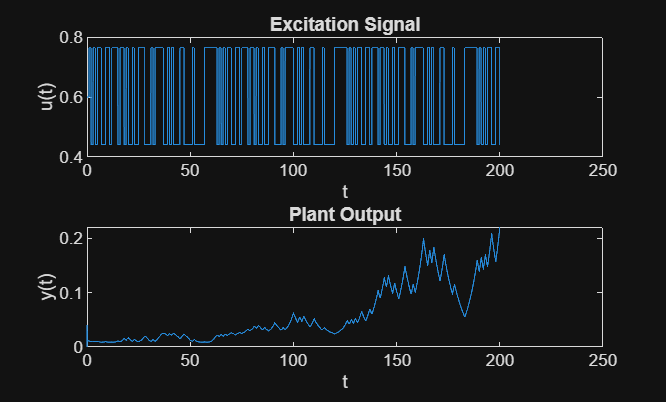

rhs = data.t;
y = data.y;
u = data.u;

subplot(2, 1, 1);
plot(rhs, u);
title('Excitation Signal'); xlabel('t'); ylabel('u(t)');
subplot(2, 1, 2);
plot(rhs, y);
title('Plant Output'); xlabel('t'); ylabel('y(t)');

### 1.2 Apply differencing

startIdx = sum(rhs < 1); % drop the data before 1s
u_cur = u(startIdx + 1 : end);
u_prev = u(startIdx : end - 1);
y_cur = y(startIdx + 1 : end);
y_prev = y(startIdx : end - 1);

delta_u = u_cur - u_prev;
delta_y = y_cur - y_prev;
fprintf("delta_u: rms=%g, nnz=%d/%d\n", rms(delta_u), nnz(delta_u), numel(delta_u));

delta_u: rms=0.000735762, nnz=104/19900001


fprintf("delta_y: rms=%g, nnz=%d/%d\n", rms(delta_y), nnz(delta_y), numel(delta_y));

delta_y: rms=2.07457e-06, nnz=199001/19900001


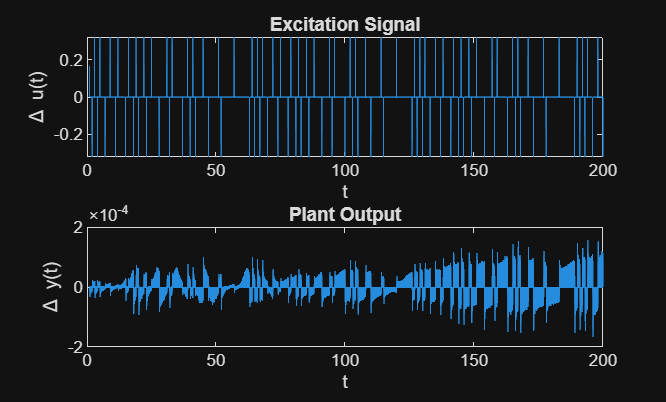


subplot(2, 1, 1);
plot(rhs(rhs >= 1), delta_u);
title('Excitation Signal'); xlabel('t'); ylabel('\Delta u(t)');
subplot(2, 1, 2);
plot(rhs(rhs >= 1), delta_y);
title('Plant Output'); xlabel('t'); ylabel('\Delta y(t)');

## 2. Choose the model structure

### 2.1 Choose orders $n_a$, $n_b$

n_a = 2;
n_b = 1;

## 3. Write the regression form

Rewrite the CARIMA as: 


$$\Delta y(k)
= -\sum_{i=1}^{n_a} a_i\,\Delta y(k-i)
+ \sum_{j=0}^{n_b} b_j\,\Delta u\!\bigl(k-1-d-j\bigr)
+ e(k)$$


Define: 

- parameter vector


$$\theta = \bigl[\, a_1 \ \cdots \ a_{n_a} \ \ b_0 \ \cdots \ b_{n_b} \,\bigr]^{T}$$


- regression vector


$$\varphi(k)=
\left[
\begin{array}{c}
-\Delta y(k-1) \\
\vdots \\
-\Delta y(k-n_a) \\
\Delta u(k-1-d) \\
\vdots \\
\Delta u(k-1-d-n_b)
\end{array}
\right]
$$


Then


$$\Delta y(k)=\varphi^{T}(k)\,\theta + e(k)$$


## 4. Estimate parameters

Collect data for $k = k_0, \ldots, k_N$, stack: 

$Y =
\left[
\begin{array}{c}
\Delta y(k_0) \\
\vdots \\
\Delta y(k_N)
\end{array}
\right]$, $\Phi =
\left[
\begin{array}{c}
\varphi^{\top}(k_0) \\
\vdots \\
\varphi^{\top}(k_N)
\end{array}
\right]$

Then: 


$$\hat{\theta}
=
\left( \Phi^{\top} \Phi \right)^{-1} \Phi^{\top} Y$$


d = 0;
p = n_a + n_b + 1;
S = zeros(p,p);
rhs = zeros(p,1);

k0 = max(n_a, n_b + d + 1) + 1;
for k = k0 : numel(delta_y)
    phi_y = -delta_y(k - 1 : -1 : k - n_a);            % n_a x 1
    phi_u = delta_u(k - 1 - d : -1 : k - 1 - d - n_b); % (n_b + 1) x 1
    phi = [phi_y; phi_u];                              % p x 1
    S = S + phi * phi';
    rhs = rhs + phi * delta_y(k);
end

theta_hat = S \ rhs;
disp(theta_hat);

     0
     0
     0
     0

